# Over-Sampling the Minority Class

One way of improving a model's predictions for a minority class is to resample the training data to reduce the class imbalance.  In the "Handling Class Imbalance" video, you saw how under-sampling the majority class (taxi trips without tolls) improved the prediction of the minority class (taxi trips with tolls).  This is the preferred approach when you have lots of data.  Taking only five percent of the majority class produced a training set with over 17,000 observations.  In a smaller data set, it may be necessary to over-sample the minority class instead.  There are three major issues to avoid when over-sampling:

    1. Placing copies of training observations in the validation and testing data sets,

    2. Creating too many copies of the over-sampled observations and creating "islands" in the training data set, and

    3. Selecting the values of the hyperparameters to avoid creating islands.

This reading will show how to over-sample the training data and avoid these pitfalls.

## Class Imbalance in the Taxi Data

Let's look at the January taxi data again.  As mentioned above, there are more than enough observations in this data set to allow under-sampling.

taxiData = importTaxiDataWithoutCleaning("yellow_tripdata_2015-01.csv");

### View Class Imbalance

Before separating the training, validation, and test data sets, let's look at the class imbalance again.  We'll use a temporary variable, `taxiTrips`, for this and save the raw `taxiData` for later.

taxiTrips = basicPreprocessing(taxiData);
taxiTrips = addWasTollPaid(taxiTrips);

taxiTrips.WasTollPaid = categorical(taxiTrips.WasTollPaid);
taxiTrips.WasTollPaid = renamecats(taxiTrips.WasTollPaid,"false","No Toll");
taxiTrips.WasTollPaid = renamecats(taxiTrips.WasTollPaid,"true","Toll");

histogram(taxiTrips.WasTollPaid)

## Partition into Training and Testing Sets

### Separate Training, Validation, and Testing Data

To avoid duplicating the over-sampled points in the test and validation sets, make these splits before oversampling.  We'll hold out 20% for testing and 20% for validation.  First, set aside the testing data.

testingPartitions = cvpartition(height(taxiData),"HoldOut",0.2);
taxiTest = taxiData(testingPartitions.test,:);
taxiTraining = taxiData(testingPartitions.training,:); 

Now, split the temporary `taxiTraining` set into training and validation sets.  Creating these sets  solves the first problem.  We are guaranteed that the observations in the test and validation sets will not be in the oversampled training data

validationPartitions = cvpartition(height(taxiTraining), "HoldOut", 0.25);
taxiValidate = taxiTraining(validationPartitions.test,:);
taxiTrain = taxiTraining(validationPartitions.training,:);

### Clean the Training Data

The training and validation data can now be pre-processed.

taxiTrain = basicPreprocessing(taxiTrain);
taxiTrain = addWasTollPaid(taxiTrain);

taxiTrain.WasTollPaid = categorical(taxiTrain.WasTollPaid);
taxiTrain.WasTollPaid = renamecats(taxiTrain.WasTollPaid,"false","No Toll");
taxiTrain.WasTollPaid = renamecats(taxiTrain.WasTollPaid,"true","Toll");

taxiValidate = basicPreprocessing(taxiValidate);
taxiValidate = addWasTollPaid(taxiValidate);

taxiValidate.WasTollPaid = categorical(taxiValidate.WasTollPaid);
taxiValidate.WasTollPaid = renamecats(taxiValidate.WasTollPaid,"false","No Toll");
taxiValidate.WasTollPaid = renamecats(taxiValidate.WasTollPaid,"true","Toll");

### Check the Distributions

It's a good idea to check that the training and validation data sets have the same class distributions as the original data set.

histogram(taxiTrain.WasTollPaid)
histogram(taxiValidate.WasTollPaid)

## Train a Model with the Original Training Data

We can use the full training data set to train a baseline model for comparison.  Only the pick-up and drop-off latitudes and longitudes are used as predictors.

predictors = ["PickupLat", "PickupLon", "DropoffLat", "DropoffLon"];
knnModel = fitcknn(taxiTrain,"WasTollPaid","NumNeighbors", 20,"PredictorNames",predictors);

yActual = taxiValidate.WasTollPaid;
yPredicted = predict(knnModel, taxiValidate);

confusionchart(yActual,yPredicted,"RowSummary","row-normalized","Title","Validation Data");

## Over-Sample the Minority Class

### Split the "Toll" and "No Toll" Trips

Separate the training data into two tables according to the `WasTollPaid` variable and calculate the ratio of trips with tolls to trips without.

taxiTrainNoToll = taxiTrain(taxiTrain.WasTollPaid == "No Toll",:);
taxiTrainToll = taxiTrain(taxiTrain.WasTollPaid == "Toll",:);

originalRatio = height(taxiTrainNoToll) / height(taxiTrainToll) % no toll / toll

### Set the under-sampling amount

Since there are more than 20 times as many trips without tolls, each trip with a toll would have to be copied 20 times to remove the class imbalance.  This can create "islands" in the training data.  For example, in a KNN model, which uses majority voting among the nearest k neighbors, a data point repeated 20 times would always "outvote" all the other nearby points for k-values less than 40.

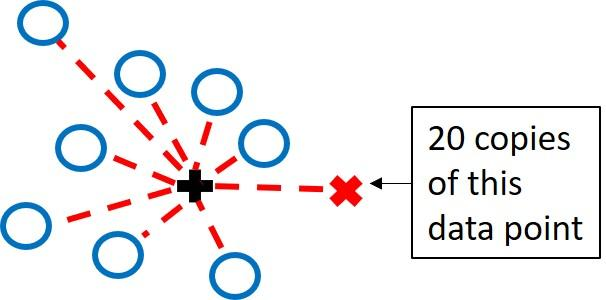

Likewise, if the number of copies of the data point is larger than the minimum leaf size, each point in the minority class could have its own leaf.

To prevent this, the majority class can be under-sampled first to reduce the amount of over-sampling required.  The slider below can set the amount of the majority class from 5% to 100% of the original data set.

underSampleFraction = 0.7;
numberToUnderSample = floor(height(taxiTrainNoToll) * underSampleFraction);
taxiTrainUnderSampled = datasample(taxiTrainNoToll, numberToUnderSample, "Replace", false); % no toll trips

### Set the over-sampling amount

Now the minority class can be over-sampled.  The `"Replace"-true` option allows `datasample` to choose the same data point more than once.

overSampleRate = 4;
numberToOverSample = height(taxiTrainToll) * overSampleRate;
taxiTrainOverSampled = datasample(taxiTrainToll, numberToOverSample, "Replace", true); % toll trips

This combination of under- and oversampling solves the second problem:  creating too many copies of the oversampled data points.

### Check the Distribution

First, check the ratio of no-toll trips to trips with tolls.

newRatio = height(taxiTrainUnderSampled) / height(taxiTrainOverSampled) % no toll / toll

Combine the under-sampled majority class and over-sampled majority class to create the new training set.

taxiTrainSampled = [taxiTrainUnderSampled; taxiTrainOverSampled];
histogram(taxiTrainSampled.WasTollPaid)

## Train a New Model

### Train and Validate the New Model

The sampled data set can now be used to train a predictive model.  The validation data is then used to create a confusion chart with the True Positive and False Negative Rates, just like the app.

knnModelSampled = fitcknn(taxiTrainSampled,"WasTollPaid","NumNeighbors",20,"PredictorNames",predictors);
yActual = taxiValidate.WasTollPaid;
yPredicted = predict(knnModelSampled, taxiValidate);
confusionchart(yActual,yPredicted,"RowSummary","row-normalized","Title","Validation Data");

## Test the Models

At this point in the Machine Learning Workflow you would normally optimize the hyperparameters.  This is more difficult with over-sampled data due to the constraints the repeated observations place on hyperparameters like Minimum Leaf Size of the Number of Neighbors.  These parameters need to be set high enough to avoid isolating the repeated observations.

Once the hyperparameters have been optimized, the final model can be applied to the test data.  Predictions are also made using the model trained without sampling for comparison.

taxiTest = basicPreprocessing(taxiTest);
taxiTest = addWasTollPaid(taxiTest);

taxiTest.WasTollPaid = categorical(taxiTest.WasTollPaid);
taxiTest.WasTollPaid = renamecats(taxiTest.WasTollPaid,"false","No Toll");
taxiTest.WasTollPaid = renamecats(taxiTest.WasTollPaid,"true","Toll");

### Used the Trained Models to Make Predictions

yActual = taxiTest.WasTollPaid;

#### Sampled Data Model

yPredictedKNN = predict(knnModelSampled, taxiTest);
confusionchart(yActual,yPredictedKNN,"RowSummary","row-normalized","Title","Sampled Data");

#### Original Data Model

yPredictedKNN = predict(knnModel, taxiTest);
confusionchart(yActual,yPredictedKNN,"RowSummary","row-normalized","Title","Original Data");